A=[2.998806	0.220528;30.323206	15.844528;23.792806	29.414528;-4.748594	12.996528;2.998806,0.220528]

A =     2.9988    0.2205
   30.3232   15.8445
   23.7928   29.4145
   -4.7486   12.9965
    2.9988    0.2205


car_location=[6.53023	3.970426]

car_location =     6.5302    3.9704


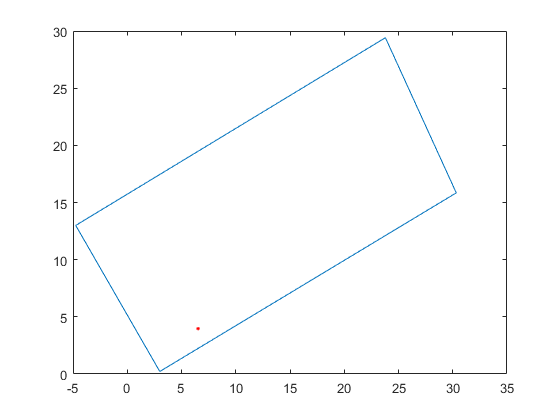

plot(A(:,1),A(:,2))
hold on
plot(car_location(1),car_location(2),"r.")

x=0:0.1:10

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


k=tan(0.5194235)

k = 0.5718

b=car_location(2)-k*car_location(1)

b = 0.2365

y=k*x+b

y =     0.2365    0.2936    0.3508    0.4080    0.4652    0.5224    0.5795    0.6367    0.6939    0.7511    0.8083    0.8654    0.9226    0.9798    1.0370    1.0942    1.1513    1.2085    1.2657    1.3229    1.3801    1.4372    1.4944    1.5516    1.6088    1.6660    1.7231    1.7803    1.8375    1.8947    1.9519    2.0090    2.0662    2.1234    2.1806    2.2378    2.2949    2.3521    2.4093    2.4665    2.5236    2.5808    2.6380    2.6952    2.7524    2.8095    2.8667    2.9239    2.9811    3.0383


k1=(A(2,2)-A(1,2))/(A(2,1)-A(1,1))

k1 = 0.5718

wheel=[6.889908928762628   4.751858863175765;
    7.3861152951527025   3.8840566155498615;
    6.170551071237373   3.189001136824235;
    5.674344704847298   4.056803384450138;6.889908928762628   4.751858863175765]

wheel =     6.8899    4.7519
    7.3861    3.8841
    6.1706    3.1890
    5.6743    4.0568
    6.8899    4.7519


plot(wheel(:,1),wheel(:,2),"b.")
lineB=[11.149906,18.121528;-3.120794,9.912528]
plot(lineB(:,1),lineB(:,2),"-")
lineC=[12.777706,15.037528;-1.492994,6.828528]
plot(lineC(:,1),lineC(:,2),"-")
kuaiD=[1.380606	2.756528;
    15.301006	10.696528;
    14.405506	11.953528;
    0.134806	3.744528]
plot(kuaiD(:,1),kuaiD(:,2))
car_body=[7.367705861024593   5.0245334969115305;
    7.863457161572001   4.157527128910811;
    5.692754138975408   2.9163265030884693;
    5.197002838428   3.7833328710891894;7.367705861024593   5.0245334969115305]
plot(car_body(:,1),car_body(:,2),"k-")

% 实例化对象
Left_front_wheel=front_wheel(0,3,0.5194235,wheel(1,:),0);
Left_rear_wheel=spot(0,3,0.5194235,wheel(4,:));
right_rear_wheel=spot(0,3,0.5194235,wheel(3,:));
Left_front_body=spot(0,3,0.5194235,car_body(1,:));
Left_rear_body=spot(0,3,0.5194235,car_body(4,:));
right_rear_body=spot(0,3,0.5194235,car_body(3,:));


% for t =0:0.01:2
%     Left_front_wheel.forward(0.5194235,0.01);
%     Left_rear_wheel.forward(0.5194235,0.01);
%     plot(Left_front_wheel.position(1,1),Left_front_wheel.position(1,2),"y.")
%     plot(Left_rear_wheel.position(1,1),Left_rear_wheel.position(1,2),"k.")
% end

degree=0.0044
while 1
    [x0,y0]=Steering_center(Left_rear_wheel.position,right_rear_wheel.position,Left_front_wheel.position,degree)
    Left_rear_wheel.direction=tangent([x0,y0],Left_rear_wheel.position)
    Left_rear_wheel.forward(0.01)
    Left_front_body.direction=tangent([x0,y0],Left_front_body.position)
    Left_front_body.forward(0.01)
    Left_rear_body.direction=tangent([x0,y0],Left_rear_body.position)
    Left_rear_body.forward(0.01)
    right_rear_body.direction=tangent([x0,y0],right_rear_body.position)
    right_rear_body.forward(0.01)
    right_rear_wheel.direction=tangent([x0,y0],right_rear_wheel.position)
    right_rear_wheel.forward(0.01)

    if 0.5127-degree>0.0044
        degree=degree+0.0044
    else
        degree=0.5124
    end
    
    Left_front_wheel.turn(degree)
    Left_front_wheel.forward(0.01)
    
    break
end


% for i=1:4
%     p1.x(i)=car_body(i,1);p2.x(i)=kuaiD(i,1);
%     p1.y(i)=car_body(i,2);p2.y(i)=kuaiD(i,2);
% end
% mind = min_dist_between_two_polygons(p1,p2,1)